clear all

First just replicate graphs in paper

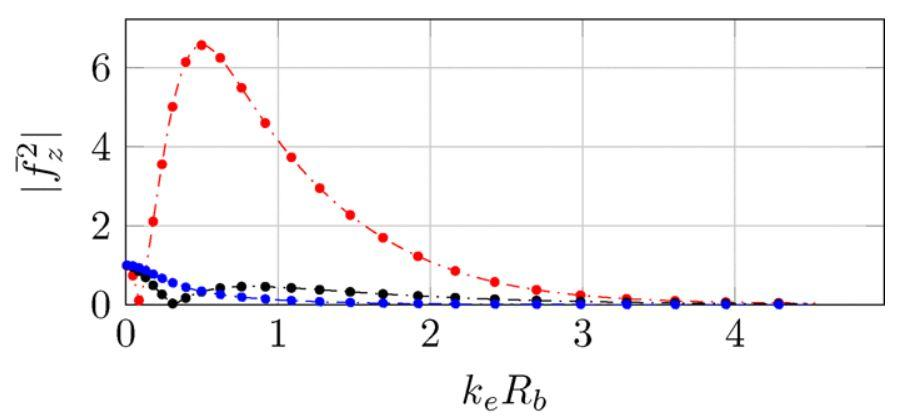

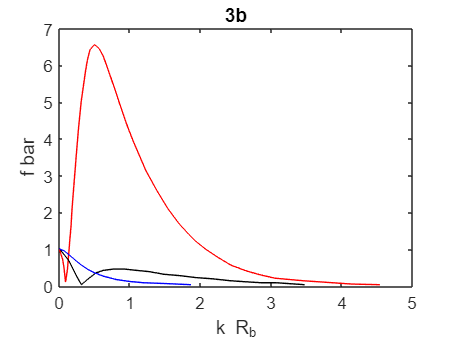

% 3b
data_3b_alpha_2 = readmatrix("3b_red");
data_3b_alpha_1 = readmatrix("3b_black");
data_3b_alpha_pt51 = readmatrix("3b_blue");

kRb_3b_alpha_2 = data_3b_alpha_2(:,1);
f_3b_alpha_2 = data_3b_alpha_2(:,2);
kRb_3b_alpha_1 = data_3b_alpha_1(:,1);
f_3b_alpha_1 = data_3b_alpha_1(:,2);
kRb_3b_alpha_pt51 = data_3b_alpha_pt51(:,1);
f_3b_alpha_pt51 = data_3b_alpha_pt51(:,2);

figure
plot(kRb_3b_alpha_2,f_3b_alpha_2,'r')
hold on
plot(kRb_3b_alpha_1,f_3b_alpha_1,'k')
plot(kRb_3b_alpha_pt51,f_3b_alpha_pt51,'b')
xlabel('k R_b')
ylabel('f bar')
title('3b')

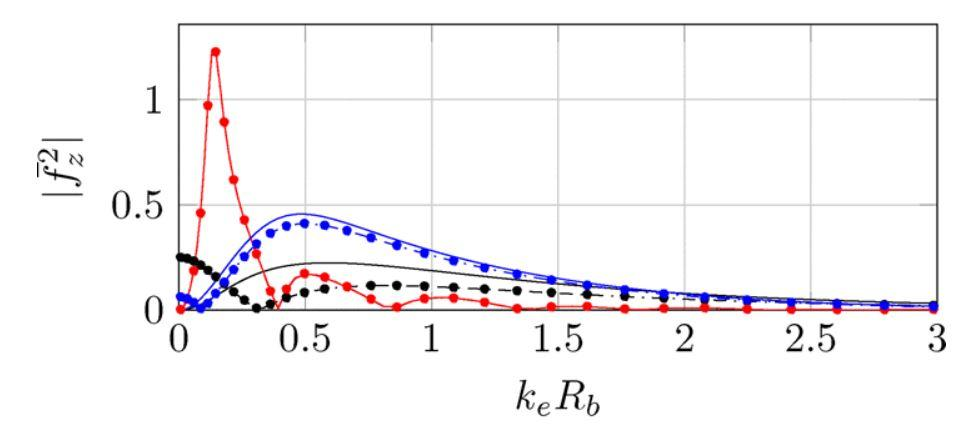

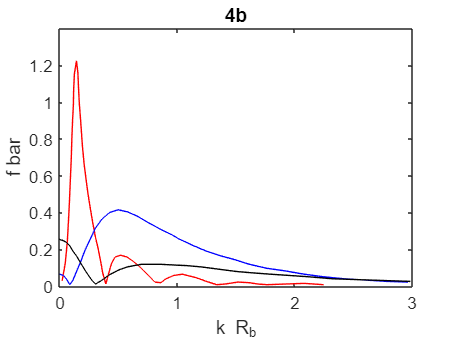

% 4b
data_4b_alpha_8 = readmatrix("4b_red");
data_4b_alpha_2 = readmatrix("4b_blue");
data_4b_alpha_1 = readmatrix("4b_black");

kRb_4b_alpha_8 = data_4b_alpha_8(:,1);
f_4b_alpha_8 = data_4b_alpha_8(:,2);
kRb_4b_alpha_2 = data_4b_alpha_2(:,1);
f_4b_alpha_2 = data_4b_alpha_2(:,2);
kRb_4b_alpha_1 = data_4b_alpha_1(:,1);
f_4b_alpha_1 = data_4b_alpha_1(:,2);

figure
plot(kRb_4b_alpha_8,f_4b_alpha_8,'r')
hold on
plot(kRb_4b_alpha_2,f_4b_alpha_2,'b')
plot(kRb_4b_alpha_1,f_4b_alpha_1,'k')
xlabel('k R_b')
ylabel('f bar')
title('4b')

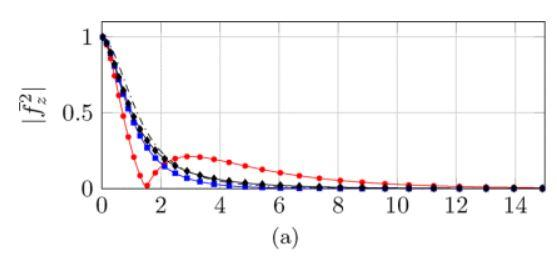

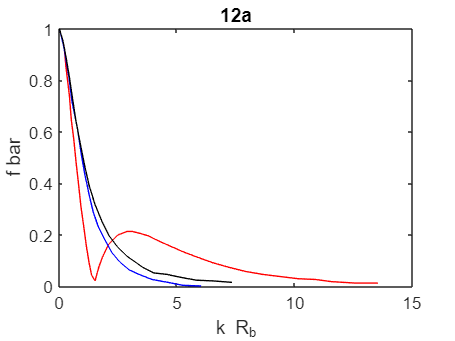

% 12a
data_12a_alpha_1 = readmatrix("12a_red");
data_12a_alpha_pt75 = readmatrix("12a_blue");
data_12a_alpha_pt51 = readmatrix("12a_black");

kRb_12a_alpha_1 = data_12a_alpha_1(:,1);
f_12a_alpha_1 = data_12a_alpha_1(:,2);
kRb_12a_alpha_pt75 = data_12a_alpha_pt75(:,1);
f_12a_alpha_pt75 = data_12a_alpha_pt75(:,2);
kRb_12a_alpha_pt51 = data_12a_alpha_pt51(:,1);
f_12a_alpha_pt51 = data_12a_alpha_pt51(:,2);

figure
plot(kRb_12a_alpha_1,f_12a_alpha_1,'r')
hold on
plot(kRb_12a_alpha_pt75,f_12a_alpha_pt75,'b')
plot(kRb_12a_alpha_pt51,f_12a_alpha_pt51,'k')
xlabel('k R_b')
ylabel('f bar')
title('12a')

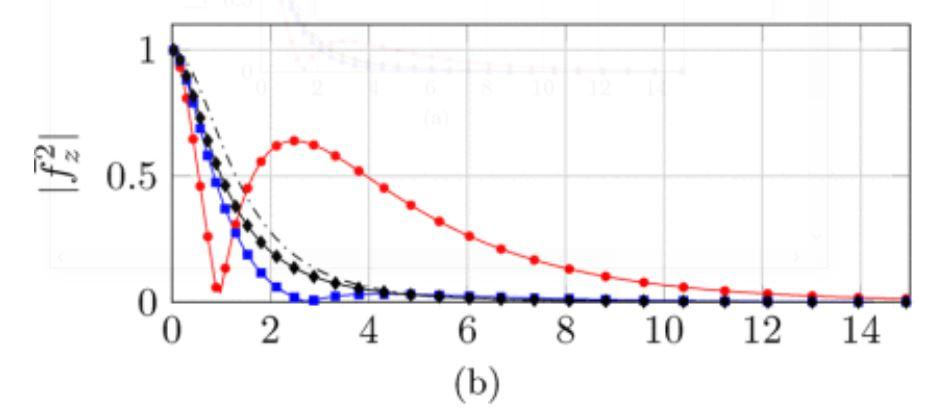

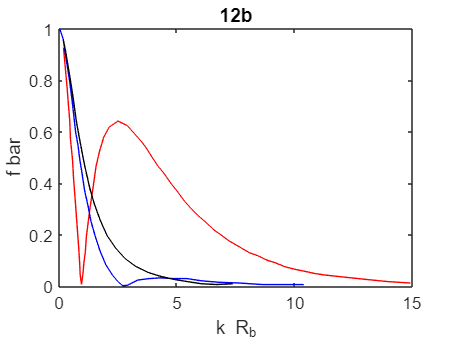

% 12b
data_12b_alpha_1 = readmatrix("12b_red");
data_12b_alpha_pt75 = readmatrix("12b_blue");
data_12b_alpha_pt51 = readmatrix("12b_black");

kRb_12b_alpha_1 = data_12b_alpha_1(:,1);
f_12b_alpha_1 = data_12b_alpha_1(:,2);
kRb_12b_alpha_pt75 = data_12b_alpha_pt75(:,1);
f_12b_alpha_pt75 = data_12b_alpha_pt75(:,2);
kRb_12b_alpha_pt51 = data_12b_alpha_pt51(:,1);
f_12b_alpha_pt51 = data_12b_alpha_pt51(:,2);
f_12b_alpha_pt75(f_12b_alpha_pt75<0) = 1e-3;

figure
plot(kRb_12b_alpha_1,f_12b_alpha_1,'r')
hold on
plot(kRb_12b_alpha_pt75,f_12b_alpha_pt75,'b')
plot(kRb_12b_alpha_pt51,f_12b_alpha_pt51,'k')
xlabel('k R_b')
ylabel('f bar')
title('12b')

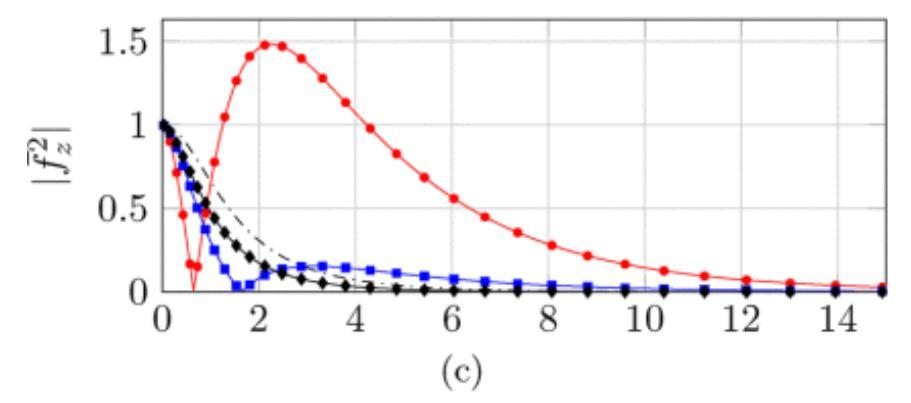

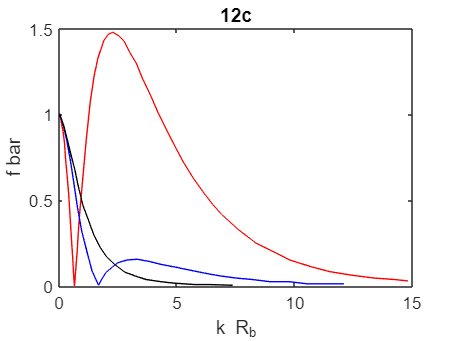

% 12c
data_12c_alpha_1 = readmatrix("12c_red");
data_12c_alpha_pt75 = readmatrix("12c_blue");
data_12c_alpha_pt51 = readmatrix("12c_black");

kRb_12c_alpha_1 = data_12c_alpha_1(:,1);
f_12c_alpha_1 = data_12c_alpha_1(:,2);
kRb_12c_alpha_pt75 = data_12c_alpha_pt75(:,1);
f_12c_alpha_pt75 = data_12c_alpha_pt75(:,2);
kRb_12c_alpha_pt51 = data_12c_alpha_pt51(:,1);
f_12c_alpha_pt51 = data_12c_alpha_pt51(:,2);

figure
plot(kRb_12c_alpha_1,f_12c_alpha_1,'r')
hold on
plot(kRb_12c_alpha_pt75,f_12c_alpha_pt75,'b')
plot(kRb_12c_alpha_pt51,f_12c_alpha_pt51,'k')
xlabel('k R_b')
ylabel('f bar')
title('12c')

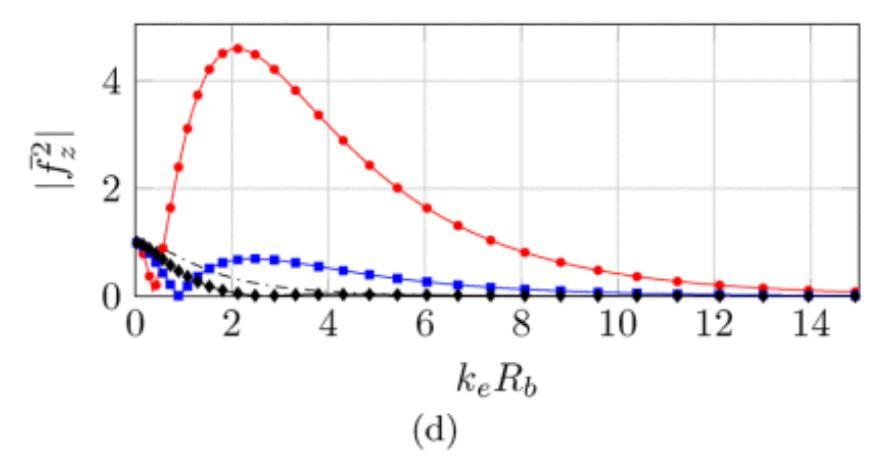

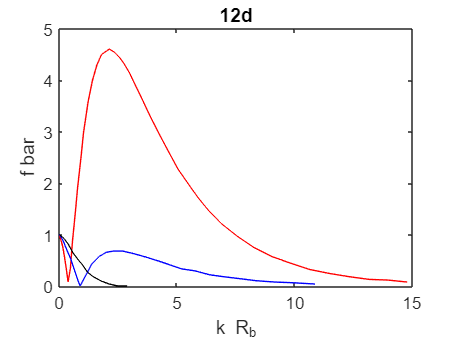

% 12d
data_12d_alpha_1 = readmatrix("12d_red");
data_12d_alpha_pt75 = readmatrix("12d_blue");
data_12d_alpha_pt51 = readmatrix("12d_black");

kRb_12d_alpha_1 = data_12d_alpha_1(:,1);
f_12d_alpha_1 = data_12d_alpha_1(:,2);
kRb_12d_alpha_pt75 = data_12d_alpha_pt75(:,1);
f_12d_alpha_pt75 = data_12d_alpha_pt75(:,2);
kRb_12d_alpha_pt51 = data_12d_alpha_pt51(:,1);
f_12d_alpha_pt51 = data_12d_alpha_pt51(:,2);
f_12d_alpha_pt51(f_12d_alpha_pt51<0) = 1e-3;

figure
plot(kRb_12d_alpha_1,f_12d_alpha_1,'r')
hold on
plot(kRb_12d_alpha_pt75,f_12d_alpha_pt75,'b')
plot(kRb_12d_alpha_pt51,f_12d_alpha_pt51,'k')
xlabel('k R_b')
ylabel('f bar')
title('12d')

Now make y-axis normalized by Rc^2 (only 4b needs to change)

beta_4b = 0.5;
f_4b_alpha_8_new = f_4b_alpha_8 * 8^2 / beta_4b^2;
f_4b_alpha_2_new = f_4b_alpha_2 * 2^2 / beta_4b^2;
f_4b_alpha_1_new = f_4b_alpha_1 * 1^2 / beta_4b^2;

Check that 3b and 4b match for alpha = 1 and 2

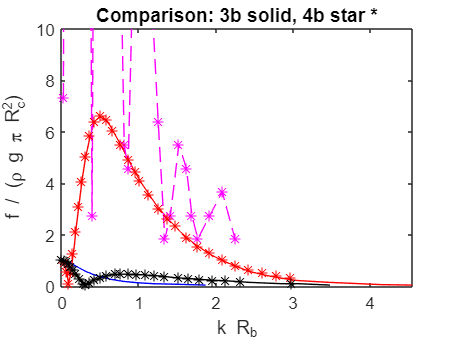

figure
plot(kRb_3b_alpha_2, f_3b_alpha_2, 'r')
hold on
plot(kRb_3b_alpha_1, f_3b_alpha_1,'k')
plot(kRb_3b_alpha_pt51, f_3b_alpha_pt51,'b')

plot(kRb_4b_alpha_8, f_4b_alpha_8_new,'m*--')
plot(kRb_4b_alpha_2, f_4b_alpha_2_new,'r*')
plot(kRb_4b_alpha_1, f_4b_alpha_1_new,'k*')
title('Comparison: 3b solid, 4b star *')
xlabel('k R_b')
ylabel('f / (\rho g \pi R_c^2)')
ylim([0 10])

Define case constants

% fig 3 and 4: case 2
% fig 12: case 4

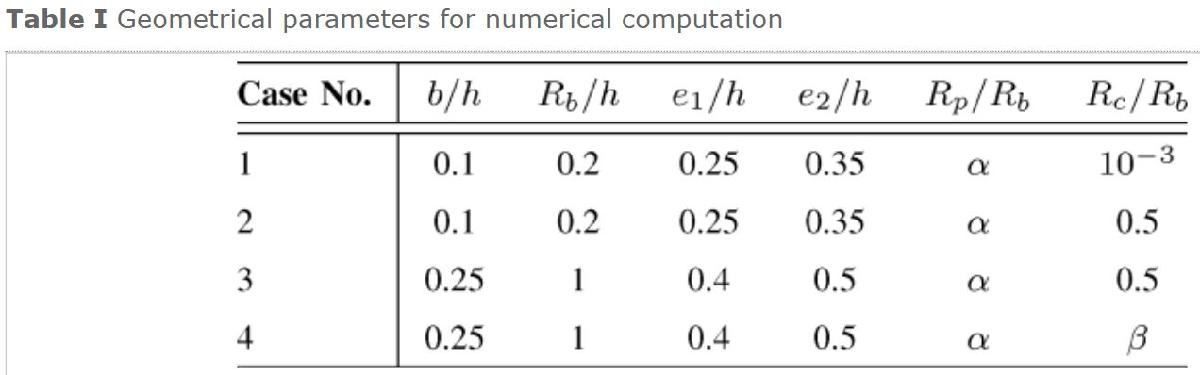

case_4_h_over_Rb = 1;
case_2_h_over_Rb = 1/.2;
case_2_e1_over_h = 0.25;
case_2_e2_over_h = 0.35;
case_4_e1_over_h = 0.4;
case_4_e2_over_h = 0.5;

Consolidate 3b and 4b into one dataset (case 2) and 12a, 12b, 12c, and 12d into another dataset (case 4)

case_2_alpha = [.51 1 2 8];
case_2_kRb = {kRb_3b_alpha_pt51 kRb_3b_alpha_1 kRb_3b_alpha_2 kRb_4b_alpha_8};
case_2_f = {f_3b_alpha_pt51 f_3b_alpha_1 f_3b_alpha_2 f_4b_alpha_8_new};

case_4_alpha = [.51 .75 1];
case_4_beta = [.5 .35 .25 .15];
% rows: alpha, cols: beta
case_4_kRb = {kRb_12a_alpha_pt51 kRb_12b_alpha_pt51 kRb_12c_alpha_pt51 kRb_12d_alpha_pt51;
              kRb_12a_alpha_pt75 kRb_12b_alpha_pt75 kRb_12c_alpha_pt75 kRb_12d_alpha_pt75;
              kRb_12a_alpha_1    kRb_12b_alpha_1    kRb_12c_alpha_1    kRb_12d_alpha_1};
case_4_f =   {f_12a_alpha_pt51 f_12b_alpha_pt51 f_12c_alpha_pt51 f_12d_alpha_pt51;
              f_12a_alpha_pt75 f_12b_alpha_pt75 f_12c_alpha_pt75 f_12d_alpha_pt75;
              f_12a_alpha_1    f_12b_alpha_1    f_12c_alpha_1    f_12d_alpha_1};


Create new signals

% create k h R_x / R_p = kRb * h/Rb * Rx/Rp (to be used for x axis)
case_2_Rx_over_Rp = max(1./case_2_alpha,1);
fun = @(cell,idx_alpha) cell .* case_2_Rx_over_Rp(idx_alpha) * case_2_h_over_Rb;
case_2_kh_Rx_over_Rp = cellfun(fun, case_2_kRb, num2cell(1:4), 'UniformOutput',false);

case_4_Rx_over_Rp = max(1./case_4_alpha,1);
fun = @(cell,idx_alpha) cell .* case_4_Rx_over_Rp(idx_alpha) * case_4_h_over_Rb;
case_4_kh_Rx_over_Rp = cellfun(fun, case_4_kRb, num2cell([1 1 1 1; 2 2 2 2; 3 3 3 3]), 'UniformOutput',false);

% also create k R_x
case_2_Rx_over_Rb = max(case_2_alpha,1);
fun = @(cell,idx_alpha) cell .* case_2_Rx_over_Rb(idx_alpha);
case_2_kRx = cellfun(fun, case_2_kRb, num2cell(1:4), 'UniformOutput',false);

case_4_Rx_over_Rb = max(case_4_alpha,1);
fun = @(cell,idx_alpha) cell .* case_4_Rx_over_Rb(idx_alpha);
case_4_kRx = cellfun(fun, case_4_kRb, num2cell([1 1 1 1; 2 2 2 2; 3 3 3 3]), 'UniformOutput',false);

% also create kh
fun = @(cell) cell .* case_2_h_over_Rb;
case_2_kh = cellfun(fun, case_2_kRb, 'UniformOutput',false);

fun = @(cell) cell .* case_4_h_over_Rb;
case_4_kh = cellfun(fun, case_4_kRb, 'UniformOutput',false);


Plots for case 2

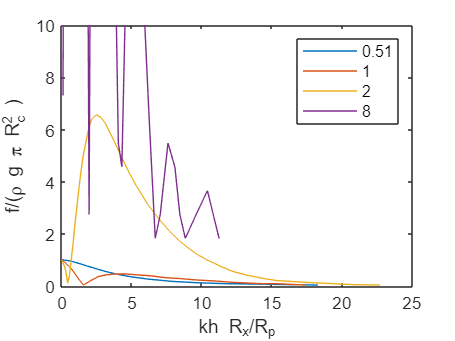

figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}, case_2_f{i_alpha} )
    hold on
end
ylim([0 10])
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p')
ylabel('f/(\rho g \pi R_c^2 )')

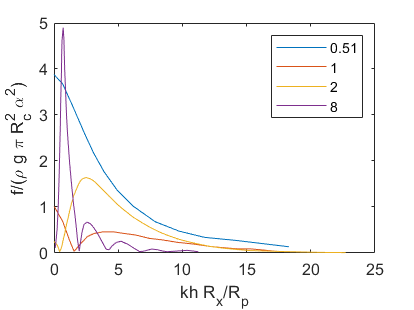


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}, case_2_f{i_alpha} / case_2_alpha(i_alpha)^2 )
    hold on
end
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p')
ylabel('f/(\rho g \pi R_c^2 \alpha^2)')

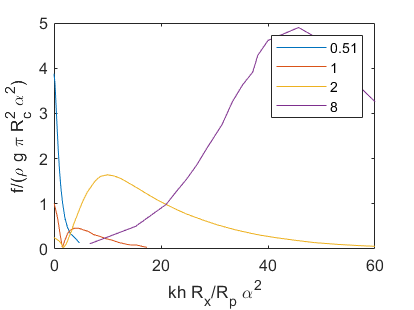


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}*case_2_alpha(i_alpha)^2, case_2_f{i_alpha} / case_2_alpha(i_alpha)^2 )
    hold on
end
xlim([0 60])
ylim([0 5])
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p \alpha^2')
ylabel('f/(\rho g \pi R_c^2 \alpha^2)')

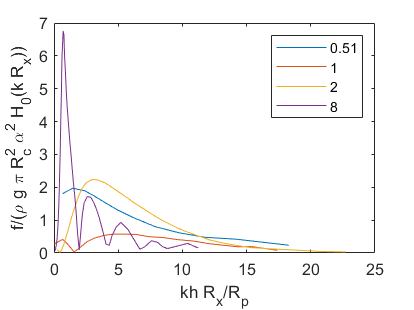


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}, case_2_f{i_alpha} / case_2_alpha(i_alpha)^2 ./ abs( besselh(0,case_2_kRx{i_alpha})) )
    hold on
end
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p')
ylabel('f/(\rho g \pi R_c^2 \alpha^2 H_0(k R_x))')

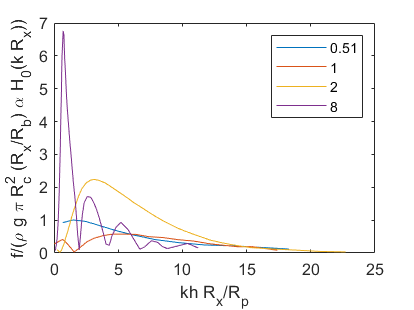


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}, case_2_f{i_alpha} / case_2_Rx_over_Rb(i_alpha) / case_2_alpha(i_alpha) ./ abs( besselh(0,case_2_kRx{i_alpha})) )
    hold on
end
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p')
ylabel('f/(\rho g \pi R_c^2 (R_x/R_b) \alpha H_0(k R_x))')

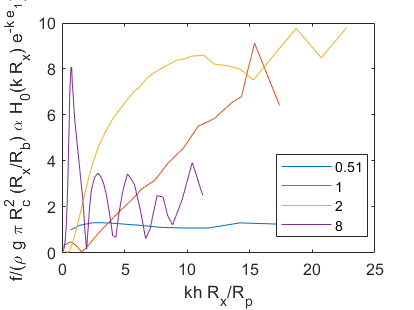


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}, case_2_f{i_alpha} / case_2_Rx_over_Rb(i_alpha) / case_2_alpha(i_alpha) ./ abs( besselh(0,case_2_kRx{i_alpha})) ./ exp(-case_2_kh{i_alpha} * case_2_e1_over_h) )
    hold on
end
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p')
ylabel('f/(\rho g \pi R_c^2 (R_x/R_b) \alpha H_0(k R_x) e^{-k e_1})')
legend('location','best')

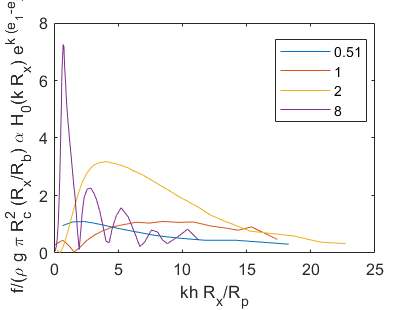


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}, case_2_f{i_alpha} / case_2_Rx_over_Rb(i_alpha) / case_2_alpha(i_alpha) ./ abs( besselh(0,case_2_kRx{i_alpha})) ./ exp(case_2_kh{i_alpha} * (case_2_e1_over_h-case_2_e2_over_h)) )
    hold on
end
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p')
ylabel('f/(\rho g \pi R_c^2 (R_x/R_b) \alpha H_0(k R_x) e^{k (e_1-e_2)})')
legend('location','best')

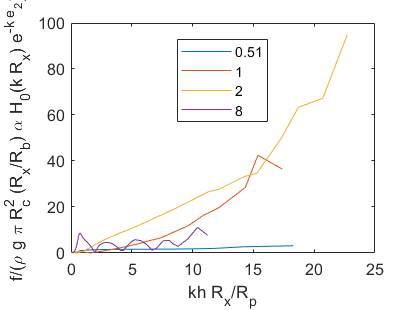


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}, case_2_f{i_alpha} / case_2_Rx_over_Rb(i_alpha) / case_2_alpha(i_alpha) ./ abs( besselh(0,case_2_kRx{i_alpha})) ./ exp(-case_2_kh{i_alpha} * case_2_e2_over_h) )
    hold on
end
legend(string(num2cell(case_2_alpha)))
xlabel('kh R_x/R_p')
ylabel('f/(\rho g \pi R_c^2 (R_x/R_b) \alpha H_0(k R_x) e^{-k e_2})')
legend('location','best')

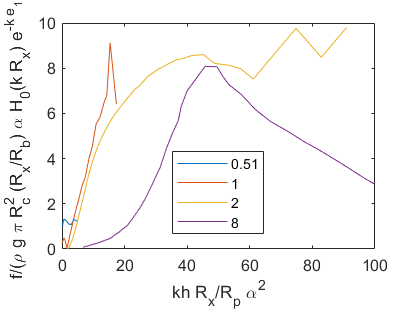


figure
for i_alpha=1:4
    plot(case_2_kh_Rx_over_Rp{i_alpha}*case_2_alpha(i_alpha)^2, case_2_f{i_alpha} / case_2_Rx_over_Rb(i_alpha) / case_2_alpha(i_alpha) ./ abs( besselh(0,case_2_kRx{i_alpha})) ./ exp(-case_2_kh{i_alpha} * case_2_e1_over_h) )
    hold on
end
legend(string(num2cell(case_2_alpha)))
xlim([0 100])
xlabel('kh R_x/R_p \alpha^2')
ylabel('f/(\rho g \pi R_c^2 (R_x/R_b) \alpha H_0(k R_x) e^{-k e_1})')
legend('location','best')

Plots for case 4

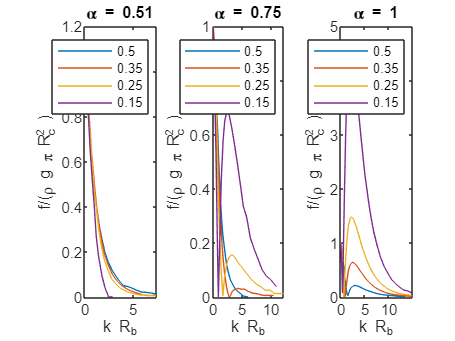

figure
for i_alpha=1:3
    subplot(1,3,i_alpha)
    for j_beta = 1:4
        plot(case_4_kRb{i_alpha, j_beta}, case_4_f{i_alpha, j_beta} )
        hold on
    end
    legend(string(num2cell(case_4_beta)))
    xlabel('k R_b')
    ylabel('f/(\rho g \pi R_c^2 )')
    title(['\alpha = ' num2str(case_4_alpha(i_alpha))] )
end

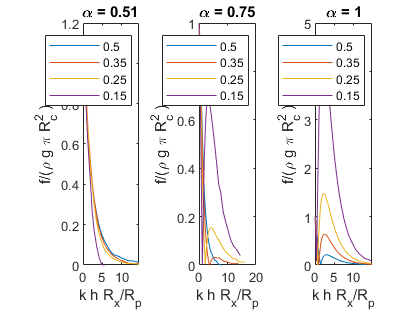


figure
for i_alpha=1:3
    subplot(1,3,i_alpha)
    for j_beta = 1:4
        plot(case_4_kh_Rx_over_Rp{i_alpha, j_beta}, case_4_f{i_alpha, j_beta} )
        hold on
    end
    legend(string(num2cell(case_4_beta)))
    xlabel('k h R_x/R_p')
    ylabel('f/(\rho g \pi R_c^2 )')
    title(['\alpha = ' num2str(case_4_alpha(i_alpha))] )
end

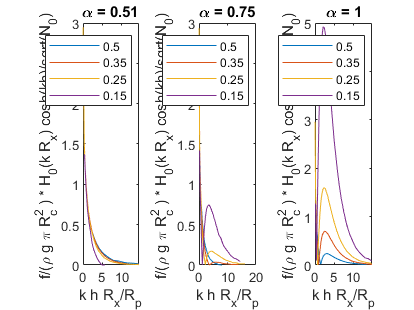


figure
for i_alpha=1:3
    subplot(1,3,i_alpha)
    for j_beta = 1:4
        x = case_4_kh_Rx_over_Rp{i_alpha, j_beta};
        kh = case_4_kh{i_alpha, j_beta};
        N0 = .5 * (1 + sinh(2 * kh) ./ (2* kh));
        scaling = abs( besselh(0,case_4_kRx{i_alpha, j_beta})) .* cosh(kh) ./ sqrt(N0);
        plot(x, case_4_f{i_alpha, j_beta} .* scaling )
        hold on
    end
    legend(string(num2cell(case_4_beta)))
    xlabel('k h R_x/R_p')
    ylabel('f/(\rho g \pi R_c^2 ) * H_0(k R_x) cosh(kh)/sqrt(N_0) ')
    title(['\alpha = ' num2str(case_4_alpha(i_alpha))] )
end

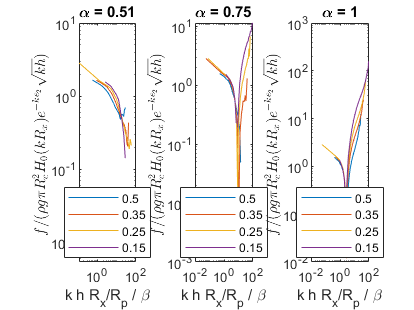


figure
for i_alpha=1:3
    subplot(1,3,i_alpha)
    for j_beta = 1:4
        x = case_4_kh_Rx_over_Rp{i_alpha, j_beta} / case_4_beta(j_beta);
        kh = case_4_kh{i_alpha, j_beta};
        N0 = .5 * (1 + sinh(2 * kh) ./ (2* kh));
        exponent = kh * case_4_e2_over_h;%* max(.3./(case_4_alpha(i_alpha)^2*case_4_beta(j_beta)), .3/.13)*.13;
        scaling = 1 ./ abs( besselh(0,case_4_kRx{i_alpha, j_beta})) ./ exp(-exponent) ./ sqrt(kh);%exp(case_4_kRx{i_alpha, j_beta}/case_4_alpha(i_alpha)); %
        y = case_4_f{i_alpha, j_beta} .* scaling; 
        loglog(x, y)
        hold on
    end
    legend(string(num2cell(case_4_beta)),'location','best')
    xlabel('k h R_x/R_p / \beta')
    ylabel('$f/(\rho g \pi R_c^2  H_0(k R_x) e^{-k e_2}\sqrt{kh})$ ','Interpreter','latex')
    title(['\alpha = ' num2str(case_4_alpha(i_alpha))] )
end

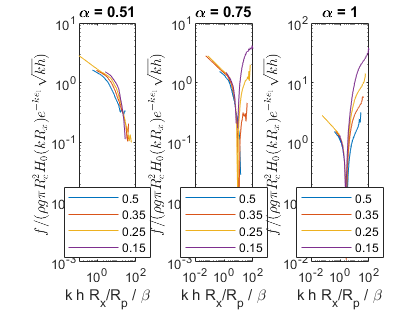



figure
for i_alpha=1:3
    subplot(1,3,i_alpha)
    for j_beta = 1:4
        x = case_4_kh_Rx_over_Rp{i_alpha, j_beta} / case_4_beta(j_beta);
        kh = case_4_kh{i_alpha, j_beta};
        N0 = .5 * (1 + sinh(2 * kh) ./ (2* kh));
        exponent = kh * case_4_e1_over_h;%* max(.3./(case_4_alpha(i_alpha)^2*case_4_beta(j_beta)), .3/.13)*.13;
        scaling = 1 ./ abs( besselh(0,case_4_kRx{i_alpha, j_beta})) ./ exp(-exponent) ./ sqrt(kh);%exp(case_4_kRx{i_alpha, j_beta}/case_4_alpha(i_alpha)); %
        y = case_4_f{i_alpha, j_beta} .* scaling; 
        loglog(x, y)
        hold on
    end
    legend(string(num2cell(case_4_beta)),'location','best')
    xlabel('k h R_x/R_p / \beta')
    ylabel('$f/(\rho g \pi R_c^2  H_0(k R_x) e^{-k e_1}\sqrt{kh})$ ','Interpreter','latex')
    title(['\alpha = ' num2str(case_4_alpha(i_alpha))] )
end

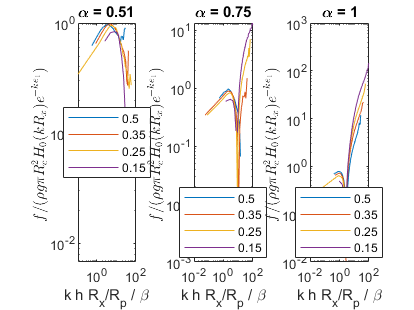


figure
for i_alpha=1:3
    subplot(1,3,i_alpha)
    for j_beta = 1:4
        x = case_4_kh_Rx_over_Rp{i_alpha, j_beta} / case_4_beta(j_beta);
        kh = case_4_kh{i_alpha, j_beta};
        N0 = .5 * (1 + sinh(2 * kh) ./ (2* kh));
        exponent = kh * case_4_e1_over_h;%* max(.3./(case_4_alpha(i_alpha)^2*case_4_beta(j_beta)), .3/.13)*.13;
        scaling = 1 ./ abs( besselh(0,case_4_kRx{i_alpha, j_beta})) ./ exp(-exponent);%exp(case_4_kRx{i_alpha, j_beta}/case_4_alpha(i_alpha)); %
        y = case_4_f{i_alpha, j_beta} .* scaling; 
        loglog(x, y)
        hold on
    end
    legend(string(num2cell(case_4_beta)),'location','best')
    xlabel('k h R_x/R_p / \beta')
    ylabel('$f/(\rho g \pi R_c^2  H_0(k R_x) e^{-k e_1})$ ','Interpreter','latex')
    title(['\alpha = ' num2str(case_4_alpha(i_alpha))] )
end

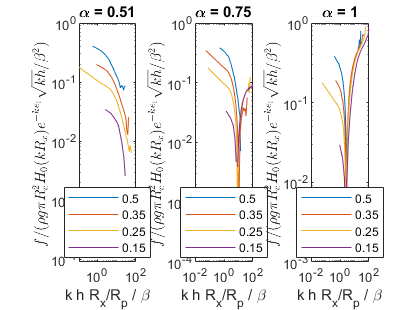


figure
for i_alpha=1:3
    subplot(1,3,i_alpha)
    for j_beta = 1:4
        x = case_4_kh_Rx_over_Rp{i_alpha, j_beta} / case_4_beta(j_beta);
        kh = case_4_kh{i_alpha, j_beta};
        N0 = .5 * (1 + sinh(2 * kh) ./ (2* kh));
        exponent = kh * case_4_e1_over_h;%* max(.3./(case_4_alpha(i_alpha)^2*case_4_beta(j_beta)), .3/.13)*.13;
        scaling = case_4_beta(j_beta)^2 ./ abs( besselh(0,case_4_kRx{i_alpha, j_beta})) ./ exp(-exponent) ./ sqrt(kh);%exp(case_4_kRx{i_alpha, j_beta}/case_4_alpha(i_alpha)); %
        y = case_4_f{i_alpha, j_beta} .* scaling; 
        loglog(x, y)
        hold on
    end
    legend(string(num2cell(case_4_beta)),'location','best')
    xlabel('k h R_x/R_p / \beta')
    ylabel('$f/(\rho g \pi R_c^2  H_0(k R_x) e^{-k e_1}\sqrt{kh}/\beta^2)$ ','Interpreter','latex')
    title(['\alpha = ' num2str(case_4_alpha(i_alpha))] )
end


% create k h R_x / R_p * alpha^2 / beta
fun = @(cell,idx_alpha,idx_beta) cell .* case_4_alpha(idx_alpha).^2 ./ case_4_beta(idx_beta);
case_4_kh_Rx_over_Rp_alpha2_over_beta = cellfun(fun, case_4_kh_Rx_over_Rp,idxs_alpha_cell,idxs_beta_cell,'UniformOutput',false);

% create f / ( |H_0(k R_x)| exp(-k e_1) sqrt(kh) )
fun = @(cell,idx_alpha,idx_beta) cell ./ ( abs( besselh(0,case_4_kRx{idx_alpha, idx_beta}) ) .* exp(-case_4_kh{idx_alpha,idx_beta} * case_4_e1_over_h) .* sqrt(case_4_kh{idx_alpha,idx_beta}) );
case_4_f_over_H0_exp_sqrt_kh = cellfun(fun, case_4_f, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput',false);

% Fits
slope_term = 'C*exp(logx).^(-m1)+A*exp(logx).^m3';
x1_dip_term = 'abs(1-(exp(logx)/x1)).^m4';
ft = fittype(['log( (' slope_term ') .* ' x1_dip_term ')'],...
    dependent='logy',independent='logx',coefficients=["C" "m1" "m3" "m4" "x1" "A"]);
fo = fitoptions(ft);
fo.Lower = [0 0 0 0 0 0];
fo.StartPoint = [1.5, 1/5, 1/3, .5, 3, .5];

x_string = 'k h R_x/R_p \alpha^2 / \beta';
y_string = '$f/(\rho g \pi R_c^2  H_0(k R_x) e^{-k e_1}\sqrt{kh})$';

% manual fit
plot_fit_sep_alpha_beta(case_4_kh_Rx_over_Rp_alpha2_over_beta, case_4_f_over_H0_exp_sqrt_kh, ...
                                case_4_alpha, case_4_beta, ft, fo, x_string, y_string, false);

% auto fit
fits = plot_fit_sep_alpha_beta(case_4_kh_Rx_over_Rp_alpha2_over_beta, case_4_f_over_H0_exp_sqrt_kh, ...
                                case_4_alpha, case_4_beta, ft, fo, x_string, y_string, true);

% auto fit coeffs vs alpha/beta
plot_fit_coeffs_vs_alpha_beta(fits, case_4_alpha, case_4_beta)

plots for case 4: all alpha combined

% pre-compute base x and y for all-alpha combined plots
fun = @(c, ia, ib) c / case_4_beta(ib);
case_4_x_base = cellfun(fun, case_4_kh_Rx_over_Rp, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

fun = @(c, ia, ib) c ./ abs(besselh(0, case_4_kRx{ia,ib})) ./ exp(-case_4_kh{ia,ib} * case_4_e1_over_h) ./ case_4_kh{ia,ib} / (case_4_alpha(ia) * max(1, case_4_alpha(ia)));
case_4_y_base = cellfun(fun, case_4_f, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

fun = @(c, ia, ib) compute_fit_base(c, case_4_alpha(ia), case_4_beta(ib), case_4_kh{ia,ib});
case_4_y_pred_base = cellfun(fun, case_4_x_base, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

fun = @(c, ia, ib) c * case_4_alpha(ia)^4;
case_4_x_f3 = cellfun(fun, case_4_x_base, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

% version 1: semilogx with alpha^4 x-scaling
fun = @(c, ia, ib) c * case_4_alpha(ia)^4;
case_4_x_f1_v1 = cellfun(fun, case_4_x_base, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

fun = @(c, ia, ib) c.^2 * case_4_beta(ib)^2;
case_4_y_f1_v1 = cellfun(fun, case_4_y_base, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

% version 2: loglog with alpha^3 x-scaling
fun = @(c, ia, ib) c * case_4_alpha(ia)^3;
case_4_x_f1_v2 = cellfun(fun, case_4_x_base, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

fun = @(c, ia, ib) c.^2 * case_4_beta(ib) * (1 + case_4_beta(ib)/case_4_alpha(ia));
case_4_y_f1_v2 = cellfun(fun, case_4_y_base, idxs_alpha_cell, idxs_beta_cell, 'UniformOutput', false);

plot_fit_all_alpha_beta(case_4_x_f1_v1, case_4_y_f1_v1, case_4_x_f3, case_4_y_base, case_4_y_pred_base, ...
    case_4_alpha, case_4_beta, @semilogx, ...
    'k h R_x/R_p \alpha^4 / \beta', ...
    '$\beta^2 \left[f/(\rho g \pi R_c^2  H_0(k R_x) e^{-k e_1}kh R_x/R_b \alpha)\right]^2$ ', ...
    [0 10]);

plot_fit_all_alpha_beta(case_4_x_f1_v2, case_4_y_f1_v2, case_4_x_f3, case_4_y_base, case_4_y_pred_base, ...
    case_4_alpha, case_4_beta, @loglog, ...
    'k h R_x/R_p \alpha^3 / \beta', ...
    '$\beta(1+\beta/\alpha) \left[f/(\rho g \pi R_c^2  H_0(k R_x) e^{-k e_1}kh R_x/R_b \alpha)\right]^2$ ', ...
    [0 20]);

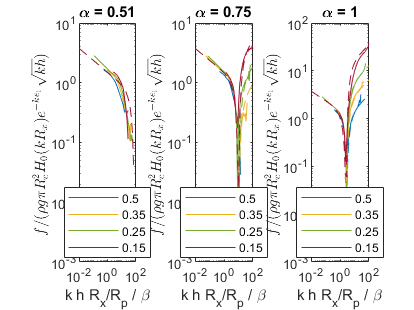


fun = @(cell,idx_alpha,idx_beta) cell .* case_4_alpha(idx_alpha).^3 ./ case_4_beta(idx_beta);
case_4_x_new = cellfun(fun, case_4_kh_Rx_over_Rp, num2cell([1 1 1 1; 2 2 2 2; 3 3 3 3]), ...

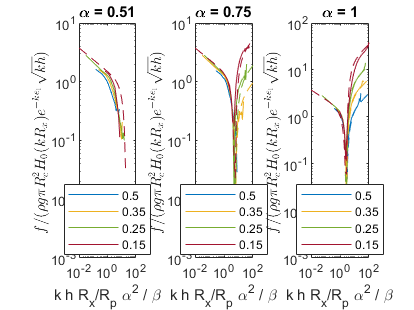

    num2cell([1 2 3 4; 1 2 3 4; 1 2 3 4]),'UniformOutput',false);

fun = @(cell,idx_alpha,idx_beta) (cell .* ( 1./abs( besselh(0,case_4_kRx{idx_alpha, idx_beta})) ./ exp(-case_4_kh{idx_alpha, idx_beta} * case_4_e1_over_h) ./ case_4_kh{idx_alpha, idx_beta} ./ case_4_alpha(idx_alpha) ./ max(1,case_4_alpha(idx_alpha)) ) ).^2 .* case_4_beta(idx_beta)*(1+case_4_beta(idx_beta)/case_4_alpha(idx_alpha));
case_4_y_new = cellfun(fun, case_4_f, num2cell([1 1 1 1; 2 2 2 2; 3 3 3 3]), ...
    num2cell([1 2 3 4; 1 2 3 4; 1 2 3 4]),'UniformOutput',false);

f4 = figure;
f5 = figure;
wn = 3;
x_log = sort([logspace(-2,2),linspace(.9*wn,1.1*wn)]);
for i_alpha=1:3
    for j_beta = 1:4

        figure(f4)
        x = case_4_x_new{i_alpha,j_beta};
        y = case_4_y_new{i_alpha,j_beta}.*x.^1.5;
        alpha_beta_label = ['\alpha=' num2str(case_4_alpha(i_alpha)) ', \beta=' num2str(case_4_beta(j_beta))];

        plot(x,y,'*','HandleVisibility','off')
        hold on
        
        z = 0.005;
        second_order_fit = @(xx) 2*sqrt((wn^1.5-xx.^1.5).^2 + (2*z*xx).^2) / wn^1.5;
        plot(x_log,second_order_fit(x_log),'DisplayName',alpha_beta_label);

        figure(f5)
        y_pred = second_order_fit(x);
        plot(x,y./y_pred,'DisplayName',alpha_beta_label)
        hold on

    end
end
figure(f4)
ax = gca();
ax.XScale = 'log';
ax.YScale = 'log';
legend('Location','best')

figure(f5)
ax = gca();
ax.XScale = 'log';
ax.YScale = 'log';
legend('Location','best')

% case_4_x_mat = cell2mat(case_4_x_new);
% case_4_y_mat = cell2mat(case_4_x_new);
case_4_alpha_mat = num2cell(case_4_alpha([1 1 1 1; 2 2 2 2; 3 3 3 3]));
case_4_beta_mat  = num2cell(case_4_beta([1 2 3 4; 1 2 3 4; 1 2 3 4]));

case_4_xyab = [case_4_x_new(:) case_4_y_new(:) case_4_alpha_mat(:) case_4_beta_mat(:)];

writecell(case_4_xyab,'case_4_xyab.csv')

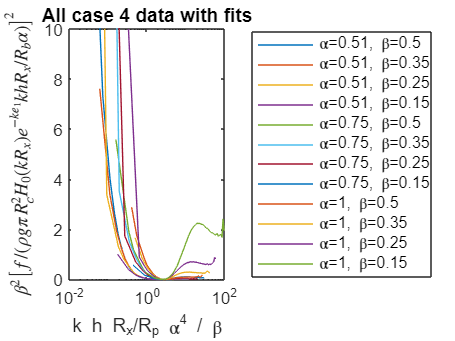

function plot_fit_coeffs_vs_alpha_beta(fits,alpha_vec,beta_vec)
cols = {'r','g','b','k'};
% coeffs vs beta for each alpha
coeff_names = coeffnames(fits{1,1});
figure
for i_alpha=1:3
    for i_coeff = 1:length(coeff_names)
        subplot(1,length(coeff_names),i_coeff)
        coeff_name = coeff_names{i_coeff};
        coeff_vals = zeros(1,4);
        for j_beta = 1:4
            f = fits{i_alpha,j_beta};
            coeff_vals(j_beta) = f.(coeff_name);
        end
        alpha_str = ['\alpha=' num2str(alpha_vec(i_alpha))];
        plot(beta_vec,coeff_vals,cols{i_alpha},'DisplayName',alpha_str)
        xlabel('\beta')
        ylabel(coeff_name)
        hold on
    end
end
legend


% coeffs vs alpha for each beta
figure
for j_beta=1:4
    for i_coeff = 1:length(coeff_names)
        subplot(1,length(coeff_names),i_coeff)
        coeff_name = coeff_names{i_coeff};
        coeff_vals = zeros(1,3);
        for i_alpha = 1:3
            f = fits{i_alpha,j_beta};
            coeff_vals(i_alpha) = f.(coeff_name);
        end
        beta_str = ['\beta=' num2str(beta_vec(j_beta))];
        plot(alpha_vec,coeff_vals,cols{j_beta},'DisplayName',beta_str)
        hold on
        xlabel('\alpha')
        ylabel(coeff_name)
    end
end
legend

end

function fits = plot_fit_sep_alpha_beta(x_cell, y_cell, alpha_vec, beta_vec, ft, fo, x_string, y_string, auto_fit_on)
    cols = {'r','g','b','k'};
    if auto_fit_on
        x_string = ['ln( ' x_string ')'];
        y_string = ['ln( ' y_string ')'];
    end
    fits = cell(size(alpha_vec));
    figure
    for i_alpha=1:3
        subplot(1,3,i_alpha)
        for j_beta = 1:4
            x = x_cell{i_alpha,j_beta};
            y = y_cell{i_alpha,j_beta};
    
            if ~auto_fit_on
                x_pred = logspace(-2,2);
                y_pred = perform_manual_fit(x_pred, alpha_vec(i_alpha), beta_vec(j_beta));

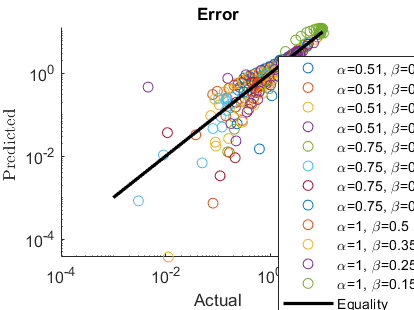

                h = loglog(x, y);
                hold on
                loglog(x_pred,abs(y_pred),'--','Color',h.Color,'HandleVisibility','off')
            else
                f = perform_auto_fit(x,y,ft,fo);
                h = plot(f,log(x),log(y));
                h(1).Color = cols{j_beta};
                h(2).Color = cols{j_beta};
                h(1).HandleVisibility = 'off';
                hold on
                fits{i_alpha,j_beta} = f;
            end

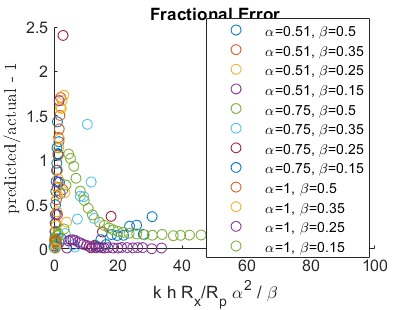

        end
        legend(string(num2cell(beta_vec)),'location','best')

        if i_alpha==2
            xlabel(x_string)
        else
            xlabel('')

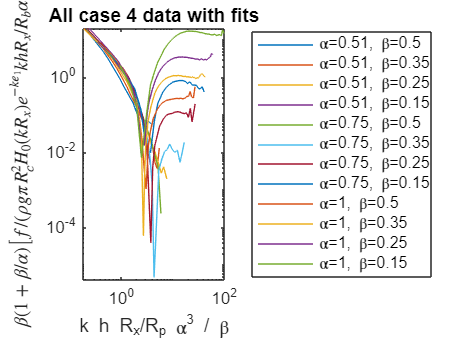

        end
        if i_alpha==1
            ylabel(y_string,'Interpreter','latex')
        else
            ylabel('')
        end
        title(['\alpha = ' num2str(alpha_vec(i_alpha))] )
    end
end

function plot_fit_one_alpha_beta(x_cell, y_cell, alpha_vec, beta_vec, ft, fo, x_string, y_string)
    cols = {'r','g','b','k'};
    figure
    for i_alpha=1:3
        for j_beta = 1:4
            x = x_cell{i_alpha,j_beta};
            y = y_cell{i_alpha,j_beta};
    
            f = perform_auto_fit(x,y,ft,fo);
            h = plot(f,log(x),log(y));
            h(1).Color = cols{j_beta};
            h(2).Color = cols{j_beta};
            h(1).HandleVisibility = 'off';
            hold on
        end
    end
    legend(string(num2cell(beta_vec)),'location','best')
    xlabel(x_string)
    ylabel(y_string,'Interpreter','latex')
end

function plot_fit_all_alpha_beta(x_f1_cell, y_f1_cell, x_f3_cell, y_cell, y_pred_cell, ...
        alpha_vec, beta_vec, f1_plot_fcn, x_f1_label, y_f1_label, y_f1_lim)
    f1 = figure; f2 = figure; f3 = figure;
    for i_alpha = 1:length(alpha_vec)
        for j_beta = 1:length(beta_vec)
            alpha_beta_label = ['\alpha=' num2str(alpha_vec(i_alpha)) ', \beta=' num2str(beta_vec(j_beta))];

            figure(f1)
            f1_plot_fcn(x_f1_cell{i_alpha, j_beta}, y_f1_cell{i_alpha, j_beta}, 'DisplayName', alpha_beta_label)
            hold on

            figure(f2)
            scatter(y_cell{i_alpha, j_beta}, y_pred_cell{i_alpha, j_beta}, 'DisplayName', alpha_beta_label)
            hold on

            figure(f3)
            scatter(x_f3_cell{i_alpha, j_beta}, y_pred_cell{i_alpha, j_beta} ./ y_cell{i_alpha, j_beta} - 1, 'DisplayName', alpha_beta_label)
            hold on
        end
    end

    figure(f1)
    legend('location','eastoutside')
    xlabel(x_f1_label)
    ylabel(y_f1_label,'Interpreter','latex')
    title('All case 4 data with fits')
    ylim(y_f1_lim)

    figure(f2)
    plot([.001 10],[.001 10],'k','LineWidth',2,'DisplayName','Equality')
    legend('location','best')
    xlabel('Actual')
    ylabel('Predicted ','Interpreter','latex')
    title('Error')
    ylim([0 13])
    ax = gca();

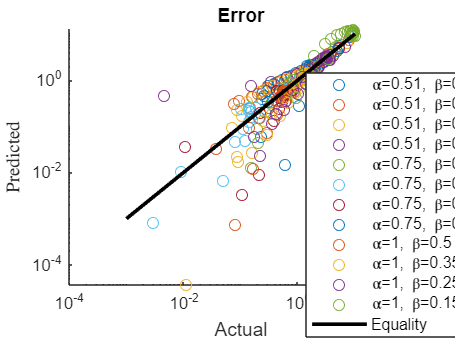

    ax.XScale = 'log';
    ax.YScale = 'log';
    legend("Position",[0.74964,0.16095,0.23964,0.47976])

    figure(f3)
    legend('location','best')
    xlabel('k h R_x/R_p \alpha^2 / \beta')
    ylabel('predicted/actual - 1','Interpreter','latex')
    title('Fractional Error')
    ylim([0 2.5])
end


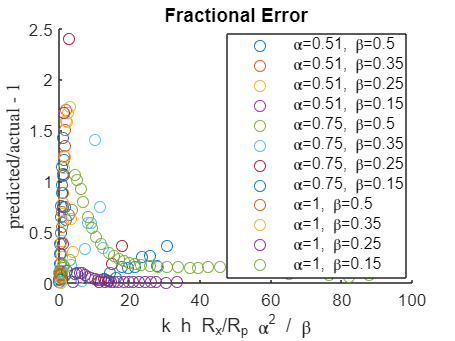

function f = perform_auto_fit(x,y,ft,fo)
    y(y<=0) = 1e-5;
    not_nan = ~isnan(x) & ~isnan(y) & x>0;
    f = fit(log(x(not_nan)), log(y(not_nan)), ft, fo);
end

function [x1, A0] = get_fit_params(alpha, beta)

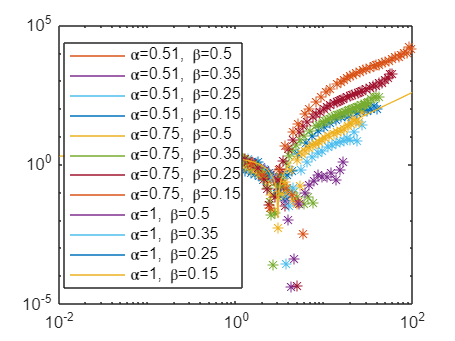

    if alpha==1
        x1 = 2.7;
        A0 = .2;
    elseif alpha==0.75
        x1 = 10;
        if beta==0.5
            A0 = 0;
        else
            A0 = 0.03;
        end
    elseif alpha==0.51
        A0 = 0;
        x1 = 80;
    end
end

function y_pred = perform_manual_fit(x_pred,alpha,beta)
    C = 1.5; % left intercept
    m1 = .2; % left slope
    m2 = 1.8;
    m3 = .3; % right slope

    [x1_0, A0] = get_fit_params(alpha, beta);
    x1 = x1_0*alpha^2;
    A = A0/beta^2;

    left_slope_term = C*x_pred.^-m1;
    right_slope_term = A*x_pred.^m3;

    left_dip_term = (1-(x_pred/x1).^m2).^2;
    right_dip_term = (1-(x1./x_pred).^m2).^2;

    switch_term = double(x_pred > x1);

    left_term = left_slope_term .* (1-switch_term) .* left_dip_term;
    right_term = right_slope_term .* switch_term .* right_dip_term;
    y_pred = left_term + right_term;
end

function y_pred = compute_fit_base(x, alpha, beta, kh)
    C = 1.5; % left intercept

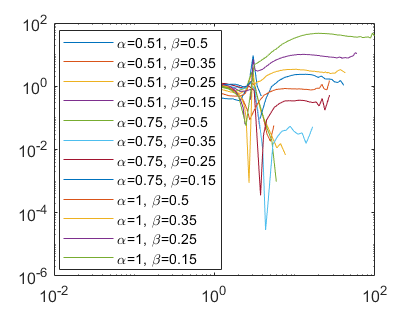

    m1 = .2; % left slope
    m2 = 1.8;
    m3 = .3; % right slope

    [x1, A0] = get_fit_params(alpha, beta);
    A = A0/beta^2;


    left_slope_term = C*x.^-m1;
    right_slope_term = A*x.^m3;

    left_dip_term = (1-(x/x1).^m2).^2;
    right_dip_term = (1-(x1./x).^m2).^2;

    switch_term = double(x > x1);

    y_pred = (left_slope_term .* (1-switch_term) .* left_dip_term + ...
              right_slope_term .* switch_term .* right_dip_term) ./ sqrt(kh) / (alpha * max(1, alpha));
end